# Time domain analysis!

# MIMO identification - short period mode

paramStruct.StopTime = "15";
run('variableLoader.m')
sim('inputs.slx');
load('doublet.mat');
load('doublet2.mat');
load('doublet3.mat');
load('zero.mat');
Ts = 0.02;
iodelay = 0;

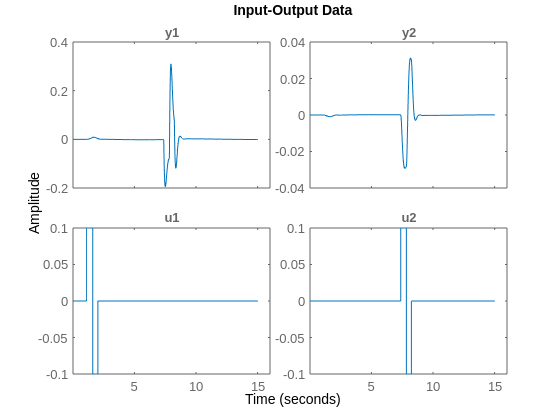

input = doublet;  %throttle
%input = zero;  %throttle
input2 = doublet2;  %elevator
out = sim('fullsys',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
%y1 = squeeze(out.velocity)-v;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-h;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2 2; 2 2];
nz = [1 2; 1 1];
data = iddata(y,u,Ts);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
plot(data)

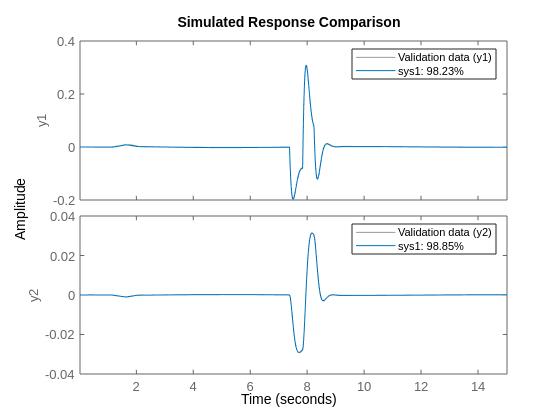

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

# MIMO identification - Phugoid mode(20secs)

paramStruct.StopTime = "50";
run('variableLoader.m')
sim('inputs.slx');
load('doublet.mat')
load('doublet2.mat')
load('doublet3.mat')
load('zero.mat');
Ts = 0.02;
iodelay = 0;

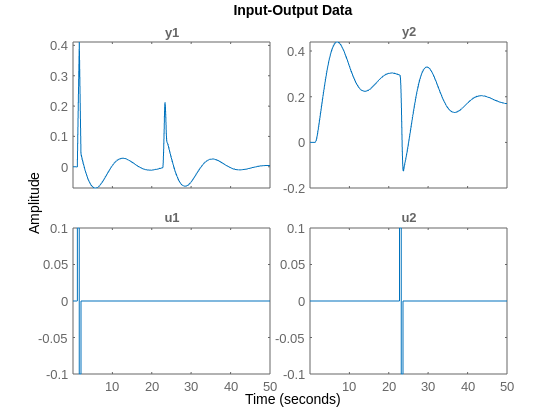

input = doublet;  %throttle
input2 = doublet3;  %elevator
%input2 = zero;  %elevator
out = sim('fullsys',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y1 = squeeze(out.velocity)-v;
%y2 = squeeze(out.gamma);
%y3 = squeeze(out.pitch_rate);
%y4 = squeeze(out.aoa)-alpha_trim;
y5 = squeeze(out.height)-h;
%y = [y1 y2 y3 y4 y5];
y = [y1 y5];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [3 2; 3 3];
nz = [1 1; 2 2];
data = iddata(y,u,Ts);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

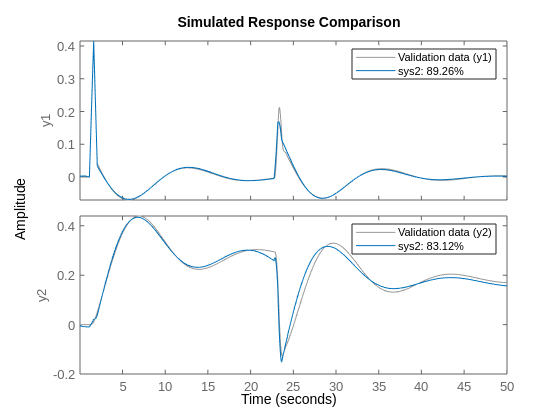

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

# system behavior:

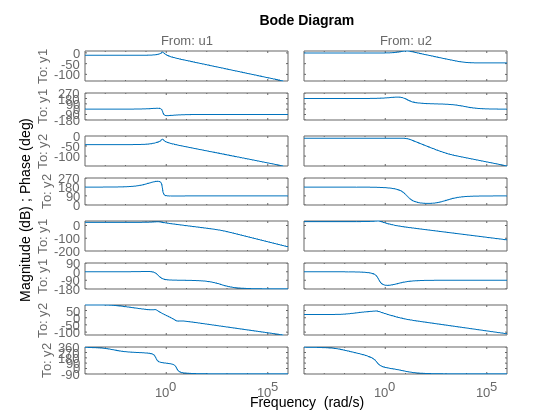

G1 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
bode(G1)